# MATLAB Fundamental Signal Processing

**Computer Applications in Transportation (2101553)**

**Siwarak Unsiwilai, Ph.D.**

Email: [siwarak.u@chula.ac.th](mailto:siwarak.u@chula.ac.th) Office: CE Building, Room 534

## Initial Step: Check for Required Toolbox

This ensures students have the necessary MATLAB tools before starting the analysis.

%% Initial Step: Check for Required Toolbox
% This lab requires the Signal Processing Toolbox.

% Clear workspace for a fresh start
clear all;
clc;
close all;

% --- Toolbox Check ---
% Use 'ver' to get version info for all toolboxes
toolbox_info = ver;

% Check if 'Image Processing Toolbox' is in the list of names
is_installed = any(strcmp({toolbox_info.Name}, 'Signal Processing Toolbox'));

% *** CORRECTED LOGIC ***
if is_installed
    disp('Success: Image Processing Toolbox is installed.');
    disp('You can run the rest of the script.');
else
    % If not installed, stop the script and show an error
    error(['Signal Processing Toolbox not found. Please install it to continue.' ...
           '\n\nTo install:' ...
           '\n1. Go to the Home tab' ...
           '\n2. Click Add-Ons > Manage Add-Ons' ...
           '\n3. Search for "Signal Processing Toolbox" and install it.' ...
           '\n4. Restart MATLAB and run this script again.']);
end

Success: Image Processing Toolbox is installed.


You can run the rest of the script.


## Part 1: Signal Generation and Time Domain

This section defines a signal as a time-series waveform.

### **1.1 **Defining Fundamental Parameters

The signal is a quantity that changes over time and can be measured, like acceleration or vibration.

% --- Signal Parameters ---

Fs = 1000;              % Sampling frequency (Hz): Samples per second.
T = 1/Fs;               % Sampling period (s)
L = 1000;               % Signal Length (number of points/samples)
t = (0:L-1)*T;          % Time vector (Time base for the signal)

% --- Signal Components ---
f1 = 50;                % Base frequency (Hz)
f2 = 150;               % Secondary frequency (Hz)

% Generate the composite signal: y(t) = 1.0 * cos(2*pi*f1*t) + 0.5 * cos(2*pi*f2*t)
y = 1.0 * cos(2*pi*f1*t) + 0.5 * cos(2*pi*f2*t);

### **1.2 Displaying the Time Domain Waveform**

The raw signal is often noisy, messy, or meaningless. In the **Time Domain**, the composite signal looks unstructured and difficult to interpret.

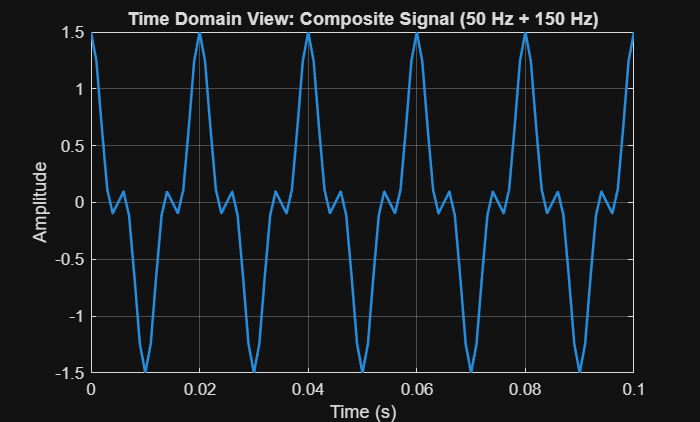

% --- Time Domain Plot ---
figure;
plot(t, y, 'LineWidth', 1.5);
title('Time Domain View: Composite Signal (50 Hz + 150 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.1]);
grid on;

## **Part 2: The Fast Fourier Transform (FFT)**

The **FFT** transforms the signal from the Time Domain into the **Frequency Domain**, revealing its spectral components5. The idea is that any signal is a sum of simple sine waves6.

### **2.1 Performing the FFT and Generating the Spectrum**

We calculate the single-sided amplitude spectrum, which shows the **amplitude** of the repeating **frequency** components (in Hertz).

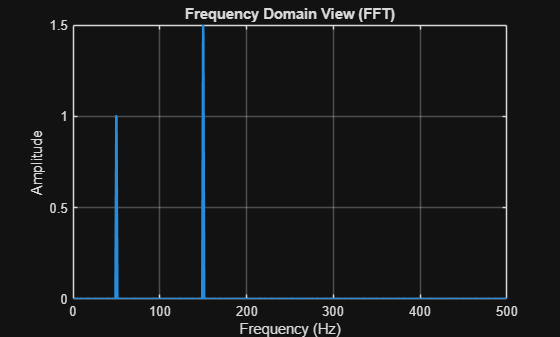

% --- STAGE 2.1: FFT CALCULATION ---

% 1. Perform the FFT
Y_fft = fft(y);

% 2. Calculate the two-sided amplitude spectrum (P2)
P2 = abs(Y_fft / L);

% 3. Calculate the single-sided amplitude spectrum (P1)
% The spectrum is symmetric; we only need the first half.
P1 = P2(1:L/2+1);
P1(2:end-1) = 2 * P1(2:end-1); % Double the magnitude (except DC and Nyquist)

% 4. Define the Frequency Vector (f)
f = Fs * (0:(L/2)) / L;

figure;
plot(f, P1, 'LineWidth', 2);
title('Frequency Domain View (FFT)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0 Fs/2]);
grid on;


disp('Observation: Clear peaks are visible at 50 Hz and 150 Hz, showing the signal components.');

Observation: Clear peaks are visible at 50 Hz and 150 Hz, showing the signal components.


## **Part 3: FFT Key Parameters and Their Impact**

The appearance and accuracy of the FFT plot are entirely dependent on the two primary sampling parameters defined in Step 1.1: **Sampling Rate** ($$\mathbf{F_s}$$) and **Signal Length** ($$\mathbf{L}$$).

### **3.1 Parameter 1: **Sampling Rate ($$\mathbf{F_s}$$) and Nyquist Frequency (Aliasing)

The **Nyquist frequency** ($$F_{Nyquist} = F_s / 2$$) is the highest frequency that can be accurately represented. 

**Activity A: Showing Correct Resolution (**$$\mathbf{F_s > 2 \cdot f_{high}}$$**)**

We set $$F_s = 2000\text{ Hz}$$ to correctly sample a $ $600\text{ Hz}$ signal ($F_{Nyquist} = 1000\text{ Hz}$)
$.

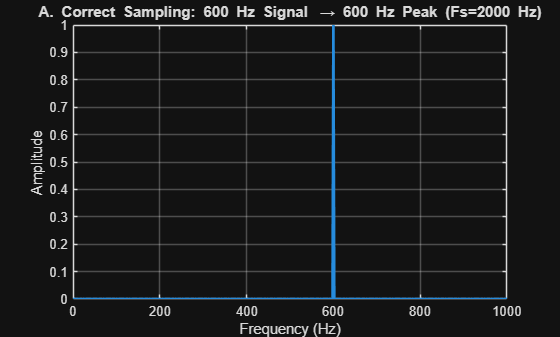

% --- STAGE 3.1A: CORRECT RESOLUTION ---

% 1. Parameters for correct sampling
Fs_correct = 2000;    % Set Fs to 2000 Hz (Nyquist = 1000 Hz)
L = 1000;             % Signal Length
T = 1/Fs_correct;
t_correct = (0:L-1)*T;

f_high = 600;         % Frequency is 600 Hz (BELOW Nyquist)

% 2. Generate and FFT
y_correct = cos(2*pi*f_high*t_correct);
Y_correct_fft = fft(y_correct);

% 3. Calculate and Plot Spectrum
P2_correct = abs(Y_correct_fft / L);
P1_correct = P2_correct(1:L/2+1);
P1_correct(2:end-1) = 2 * P1_correct(2:end-1);
f_correct = Fs_correct * (0:(L/2)) / L; 

figure;
plot(f_correct, P1_correct, 'LineWidth', 2);
title('A. Correct Sampling: 600 Hz Signal \rightarrow 600 Hz Peak (Fs=2000 Hz)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0 Fs_correct/2]);
grid on;


fprintf('Observation: Fs=%d Hz correctly resolves the %d Hz signal.\n', Fs_correct, f_high);

Observation: Fs=2000 Hz correctly resolves the 600 Hz signal.


**Activity B: Showing Correct Resolution (**$$\mathbf{F_s < 2 \cdot f_{high}}$$**)**

We set $$F_s = 1000\text{ Hz}$$ to incorrectly sample a $ $600\text{ Hz}$ signal ($F_{Nyquist} = 500\text{ Hz}$)
$.

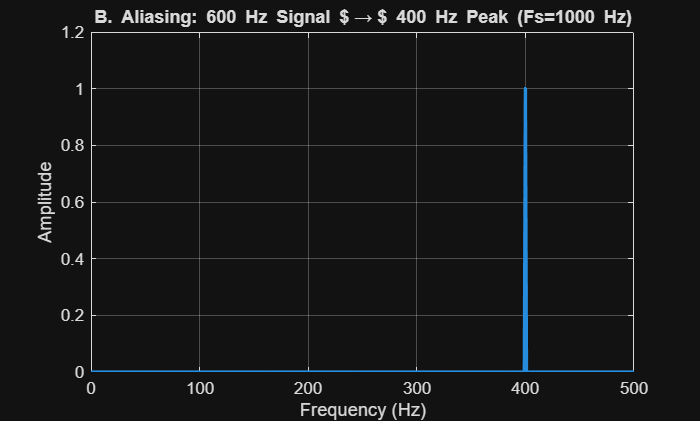

% --- STAGE 3.1B: ALIASING DEMONSTRATION ---

% 1. Parameters for undersampling
Fs_aliased = 1000;    % Set Fs to 1000 Hz (Nyquist = 500 Hz)
L = 1000;             % Signal Length
T = 1/Fs_aliased;
t_aliased = (0:L-1)*T;

f_high = 600;         % Frequency is 600 Hz (ABOVE Nyquist)

% 2. Generate and FFT
y_aliased = cos(2*pi*f_high*t_aliased);
Y_aliased_fft = fft(y_aliased);

% 3. Calculate and Plot Spectrum
P2_aliased = abs(Y_aliased_fft / L);
P1_aliased = P2_aliased(1:L/2+1);
P1_aliased(2:end-1) = 2 * P1_aliased(2:end-1);
f_aliased = Fs_aliased * (0:(L/2)) / L;

figure;
plot(f_aliased, P1_aliased, 'LineWidth', 2);
title('B. Aliasing: 600 Hz Signal $\rightarrow$ 400 Hz Peak (Fs=1000 Hz)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0 Fs_aliased/2]);
grid on;


f_apparent = abs(f_high - Fs_aliased);
fprintf('Observation: Aliasing occurs. The %d Hz signal appears incorrectly at %d Hz.\n', f_high, f_apparent);

Observation: Aliasing occurs. The 600 Hz signal appears incorrectly at 400 Hz.


### **3.2 Parameter 2: Signal Length (**$$L$$**) and Frequency Resolution (**$$\Delta f$$)

**Frequency Resolution** ($$\Delta f$$) is the smallest frequency difference the FFT can distinguish. It is defined by the formula:


$$$$\Delta f = \frac{F_s}{L}$$$$


A larger signal length ($$L$
$) results in a smaller $$\Delta f$$ and sharper, more detailed peaks.

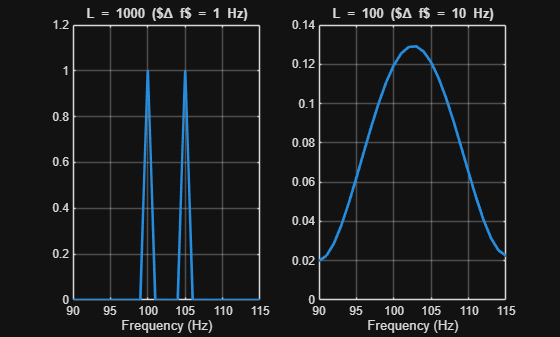

% --- STAGE 3.2: RESOLUTION DEMONSTRATION ---

% Reset Fs to 1000 Hz for this activity
Fs_res = 1000;
T = 1/Fs_res;

% Define two closely spaced frequencies
f_close_1 = 100;
f_close_2 = 105; % Separated by only 5 Hz

% --- Case 1: High Resolution (L=1000) ---
L_high = 1000; 
t_high = (0:L_high-1)*T;
y_high = cos(2*pi*f_close_1*t_high) + cos(2*pi*f_close_2*t_high);
Y_high_fft = fft(y_high);
P1_high = abs(Y_high_fft(1:L_high/2+1)) / (L_high/2);
f_high_res = Fs_res * (0:(L_high/2)) / L_high;
Delta_f_high = Fs_res / L_high;

% --- Case 2: Low Resolution (L=100) ---
L_low = 100;
t_low = (0:L_low-1)*T;
y_low = cos(2*pi*f_close_1*t_low) + cos(2*pi*f_close_2*t_low);
Y_low_fft = fft(y_low, L_high); % Pad with zeros to L_high for plotting comparison
P1_low = abs(Y_low_fft(1:L_high/2+1)) / (L_high/2);
Delta_f_low = Fs_res / L_low;


figure;
subplot(1, 2, 1);
plot(f_high_res, P1_high, 'LineWidth', 2);
title(['L = 1000 ($\Delta f$ = ', num2str(Delta_f_high), ' Hz)']);
xlabel('Frequency (Hz)');
xlim([90 115]);
grid on;

subplot(1, 2, 2);
plot(f_high_res, P1_low, 'LineWidth', 2);
title(['L = 100 ($\Delta f$ = ', num2str(Delta_f_low), ' Hz)']);
xlabel('Frequency (Hz)');
xlim([90 115]);
grid on;


disp('Observation: When resolution is high (left), peaks are separated. When resolution is low (right), peaks smear together and are unresolved.');

Observation: When resolution is high (left), peaks are separated. When resolution is low (right), peaks smear together and are unresolved.


## Part 4: Recognizing the FFT's Limitation

The core limitation of the standard Fourier Transform is that it tells us **what** frequencies are present, **but not *****when***** those frequencies happen**. This problem requires **Time-Frequency Analysis** for **non-stationary signals** like the vibration impact of a defect.

### **4.1 Creating a Non-Stationary Signal**

We return to our composite signal and add a high-frequency event that only occurs for a short duration.

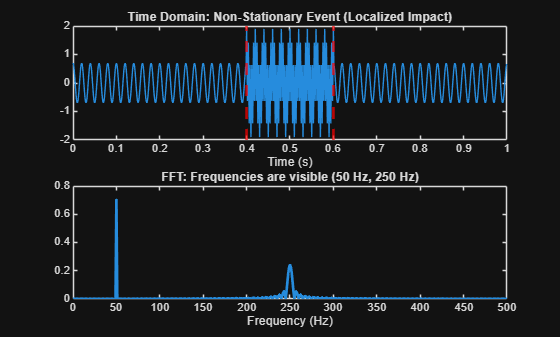

% --- STAGE 4.1: NON-STATIONARY SIGNAL ---
Fs = 1000;
L = 1000;
T = 1/Fs;
t = (0:L-1)*T;

f1 = 50;  % Continuous base frequency
f_event = 250; % Localized impact frequency

% 50 Hz base signal
y_ns = 0.7 * cos(2*pi*f1*t); 

% Add the 250 Hz event (only from 0.4s to 0.6s)
t_start = 0.4;
t_end = 0.6;
event_zone = (t >= t_start) & (t <= t_end);

y_ns(event_zone) = y_ns(event_zone) + 1.2 * cos(2*pi*f_event*t(event_zone));

% Re-plot the time signal and its standard FFT
Y_fft_ns = fft(y_ns);
P2_ns = abs(Y_fft_ns / L);
P1_ns = P2_ns(1:L/2+1);
P1_ns(2:end-1) = 2 * P1_ns(2:end-1);
f = Fs * (0:(L/2)) / L;


figure;
subplot(2, 1, 1);
plot(t, y_ns);
xline([t_start, t_end], 'r--', 'LineWidth', 2);
title('Time Domain: Non-Stationary Event (Localized Impact)');
xlabel('Time (s)');

subplot(2, 1, 2);
plot(f, P1_ns, 'LineWidth', 2);
title('FFT: Frequencies are visible (50 Hz, 250 Hz)');
xlabel('Frequency (Hz)');
xlim([0 Fs/2]);


disp('Key Takeaway: The FFT shows WHAT frequencies are present (50 Hz and 250 Hz), but looking at the FFT plot alone, you cannot tell WHEN the 250 Hz event occurred. We have lost the time information!');

Key Takeaway: The FFT shows WHAT frequencies are present (50 Hz and 250 Hz), but looking at the FFT plot alone, you cannot tell WHEN the 250 Hz event occurred. We have lost the time information!
